colobj = roomspec();
rL=.4;rW=.2;rz=.1;
robot=robotspec([rL;rW;2*rz]);
resolution = 100;
all_coloj = colobj;
all_coloj.type{15}
binary_map = colobj2binary_map(colobj, resolution);

show(binary_map);
view(-90,90);

lidar = rangeSensor;

pose = [1 1 deg2rad(45)];
for i = 1:10 % Get time multiple times
    tic
    [ranges,angles] = lidar(pose,binary_map);
    toc
end

Elapsed time is 0.055515 seconds.
Elapsed time is 0.036470 seconds.
Elapsed time is 0.034848 seconds.
Elapsed time is 0.040615 seconds.
Elapsed time is 0.033564 seconds.
Elapsed time is 0.032774 seconds.
Elapsed time is 0.037024 seconds.
Elapsed time is 0.033157 seconds.
Elapsed time is 0.047297 seconds.
Elapsed time is 0.050084 seconds.


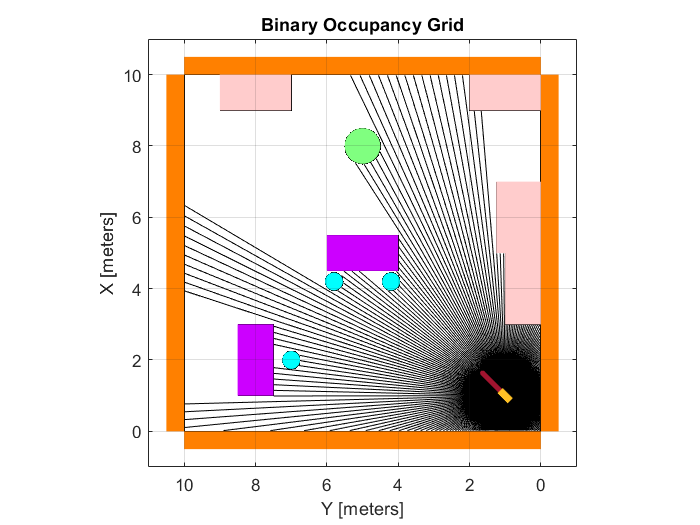


plot_scans(ranges, angles, pose);

robot=robotspec([0.4 0.2 0.2]);
hold on
robotshow(robot,pose);
roomshow(roomspec)
hold off

function plot_scans(ranges, angles, pose)
hold on

for i = 1:length(ranges)
    plot(pose(1)+[0 cos(pose(3)+angles(i))*ranges(i)], pose(2)+[0 sin(pose(3)+angles(i))*ranges(i)], 'k')
    
end

hold off
end